clc; clear; close all;

% Cargar datos
data = readtable('Five_times_Kinematics_HT_Query_final.xlsx');

isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);

% Parámetros
B = 10000;
alpha = 0.01;
lower_p = alpha/2;
upper_p = 1 - alpha/2;

% Estadísticos originales
mu = mean(X);
S = cov(X);
invS = pinv(S);

% Distancias de Mahalanobis
D2 = zeros(n,1);
for i = 1:n
    d = X(i,:) - mu;
    D2(i) = d * invS * d';
end
D2_sorted = sort(D2);
chi2_q = chi2inv(((1:n)' - 0.5) / n, p);

% Bootstrap no paramétrico
D2_boot = zeros(n, B);
for b = 1:B
    idx = randi(n, n, 1);
    Xb = X(idx, :);
    mu_b = mean(Xb);
    S_b = cov(Xb);
    invS_b = pinv(S_b);

    for i = 1:n
        d = Xb(i,:) - mu_b;
        D2_boot(i,b) = d * invS_b * d';
    end
    D2_boot(:,b) = sort(D2_boot(:,b));
end

% Banda de confianza
lower_env = quantile(D2_boot, lower_p, 2);
upper_env = quantile(D2_boot, upper_p, 2);

% Ajuste lineal
coeffs = polyfit(chi2_q, D2_sorted, 1);
y_fit = polyval(coeffs, chi2_q);
R2 = corr(chi2_q, D2_sorted)^2;

% Mostrar resultados
fprintf('--- Análisis multivariante de normalidad ---\n');

--- Análisis multivariante de normalidad ---


fprintf('Dimensiones: n = %d, p = %d\n', n, p);

Dimensiones: n = 46, p = 78


fprintf('Pendiente (ideal = 1): %.4f\n', coeffs(1));

Pendiente (ideal = 1): 0.0000


fprintf('R² (ideal = 1): %.4f\n\n', R2);

R² (ideal = 1): 0.9904



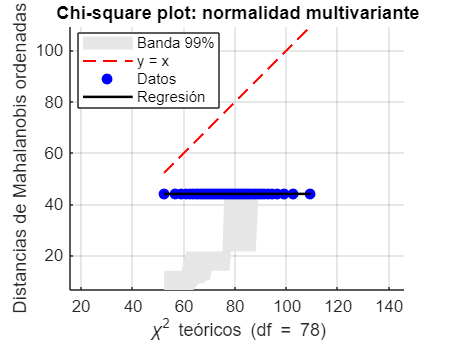


% Gráfico
figure;
hold on;
fill([chi2_q; flipud(chi2_q)], [lower_env; flipud(upper_env)], [0.9 0.9 0.9], 'EdgeColor','none');
plot(chi2_q, chi2_q, 'r--', 'LineWidth',1.2);
plot(chi2_q, D2_sorted, 'bo', 'MarkerFaceColor','b');
plot(chi2_q, y_fit, 'k-', 'LineWidth', 1.5);
hold off;

axis equal; grid on;
xlabel(sprintf('\\chi^2 teóricos (df = %d)', p));
ylabel('Distancias de Mahalanobis ordenadas');
title('Chi-square plot: normalidad multivariante');
legend('Banda 99%', 'y = x', 'Datos', 'Regresión', 'Location', 'best');